rng('default')
rng(1234)
cd /Users/serg/github_projects/QASS_SVM/data

X = transpose(-6:0.2:6);
Y = sinc ( X ) + 0.1.* rand ( size ( X ) ) ;
out = [15 17 19];
Y ( out ) = 0.7+0.3* rand ( size ( out ) ) ;
out = [41 44 46];
Y ( out ) = 1.5+0.2* rand ( size ( out ) ) ;

model = initlssvm (X , Y , 'f', [] , [] , 'RBF_kernel') ;
costFun = 'crossvalidatelssvm';
model = tunelssvm ( model , 'simplex', costFun , {10 , 'mse';}) 


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         19.0353
                                          [sig2]        0.077408
                                          F(X)=         0.13178
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   19.0353    0.0774076

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     1.317763e-01     2.9463        -2.5587      initial 
     2           5     1.317763e-01     2.9463        -2.5587      contract inside 
     3           6     1.317763e-01     2.9463        -2.5587      reflect 
     4           8     1.315311e-01     2.5713        -2.1

model = struct with fields:
           type: 'f'
          x_dim: 1
          y_dim: 1
        nb_data: 61
    kernel_type: 'RBF_kernel'
     preprocess: 'preprocess'
      prestatus: 'ok'
         xtrain: [61×1 double]
         ytrain: [61×1 double]
       selector: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61]
            gam: 8.40078882650969
    kernel_pars: 0.0878514849207389
       x_delays: 0
       y_delays: 0
          steps: 1
         latent: 'no'
           code: 'original'
       codetype: 'none'
    pre_xscheme: 'c'
    pre_yscheme: 'c'
      pre_xmean: 8.73618117737828e-17
       pre_xstd: 3.55058680596133
      pre_ymean: 0.241626046921664
       pre_ystd: 0.432349174644862
         status: 'changed'
        weights: []


figure;
plotlssvm(model)

Start Plotting...finished


ans = struct with fields:
           type: 'f'
          x_dim: 1
          y_dim: 1
        nb_data: 61
    kernel_type: 'RBF_kernel'
     preprocess: 'preprocess'
      prestatus: 'ok'
         xtrain: [61×1 double]
         ytrain: [61×1 double]
       selector: [61×1 logical]
            gam: 8.40078882650969
    kernel_pars: 0.0878514849207389
       x_delays: 0
       y_delays: 0
          steps: 1
         latent: 'no'
           code: 'original'
       codetype: 'none'
    pre_xscheme: 'c'
    pre_yscheme: 'c'
      pre_xmean: 8.73618117737828e-17
       pre_xstd: 3.55058680596133
      pre_ymean: 0.241626046921664
       pre_ystd: 0.432349174644862
         status: 'trained'
        weights: []
              b: -0.0737931593745122
          alpha: [61×1 double]
       duration: 0.00046425


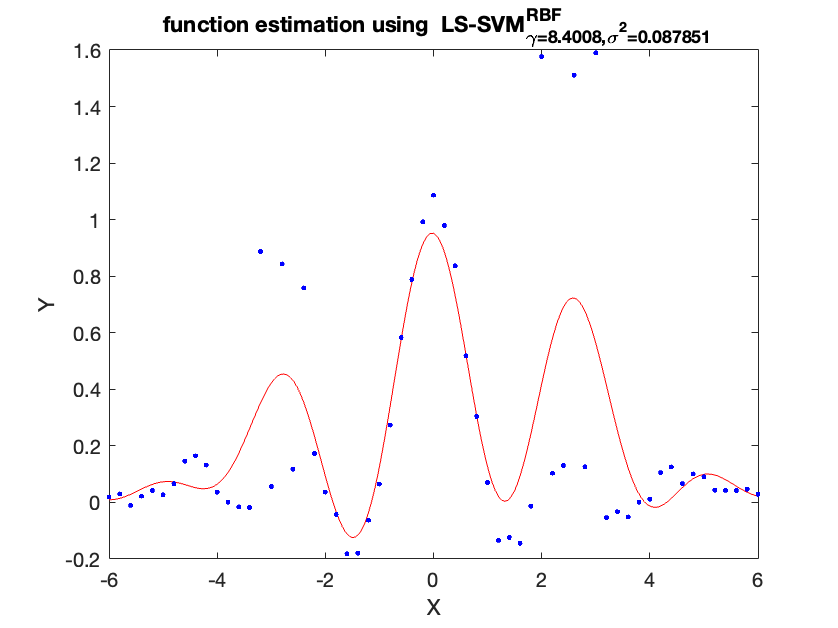

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures2/fig2_214_1.png','Resolution',300)

model = trainlssvm(model);
[Yht, Zt] = simlssvm(model, X);
err_nr = sum(sqrt((Y-Yht).^2));

model = initlssvm (X , Y , 'f', [] , [] , 'RBF_kernel') ;
costFun = 'rcrossvalidatelssvm';
wFun = 'whuber';
model = tunelssvm ( model , 'simplex', costFun , {10 , 'mae';} , wFun ) ;


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2510.1634
                                          [sig2]        0.051323
                                          F(X)=         0.14784
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  rcrossvalidatelssvm
    kernel function                 RBF_kernel

    weight function:                whuber 

 3. starting values:                   2510.1634     0.05132325

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)     log(delta)      Procedure

     1           4     1.478379e-01     7.8281        -2.9696      -4.3944        initial 
     2           6     1.478379e-01     7.8281        -2.9696      -4.3944        contract outside 
     3           7     1.478379e-01 

model = robustlssvm ( model );

Converged after 215 iteration(s)

figure;
plotlssvm(model)

Start Plotting...finished


ans = struct with fields:
           type: 'f'
          x_dim: 1
          y_dim: 1
        nb_data: 61
    kernel_type: 'RBF_kernel'
     preprocess: 'preprocess'
      prestatus: 'ok'
         xtrain: [61×1 double]
         ytrain: [61×1 double]
       selector: [61×1 logical]
            gam: [2510.16341378945 37.5263690556366 73.5183495633361 99.9588966659544 2510.16341378945 16.3631267207078 16.2401236487045 2510.16341378945 38.0850339088611 35.1665924944375 49.1601548835011 189.636375689135 2510.16341378945 … ]
    kernel_pars: 0.0513232501103828
       x_delays: 0
       y_delays: 0
          steps: 1
         latent: 'no'
           code: 'original'
       codetype: 'none'
    pre_xscheme: 'c'
    pre_yscheme: 'c'
      pre_xmean: 8.73618117737828e-17
       pre_xstd: 3.55058680596133
      pre_ymean: 0.241626046921664
       pre_ystd: 0.432349174644862
         status: 'trained'
        weights: 'whuber'
          delta: 0.0123468220250864
              b: -0.256770725884965


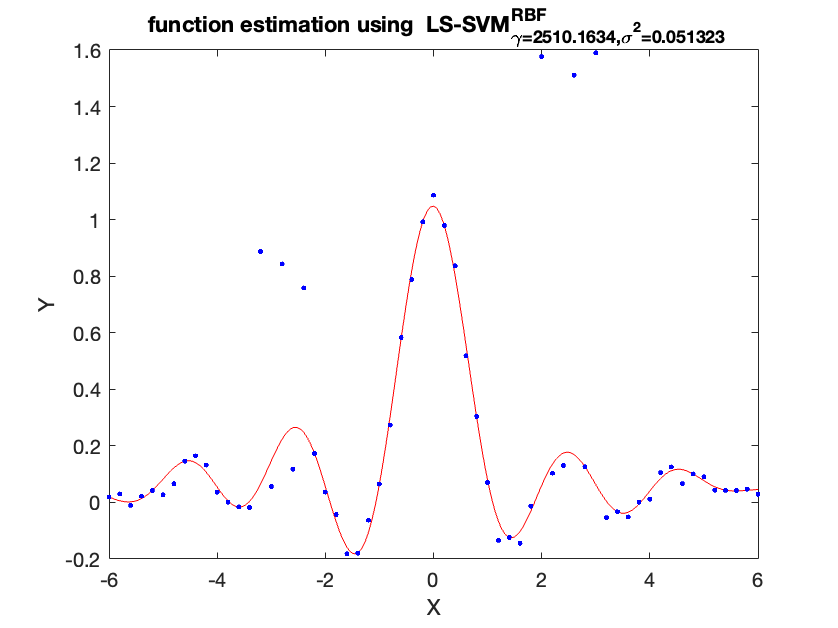

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures2/fig2_214_2.png','Resolution',300)

model = trainlssvm(model);
[Yht, Zt] = simlssvm(model, X);
err_whuber = sum(sqrt((Y-Yht).^2))

err_whuber =           7.58313157599412


% hampel weights
model = initlssvm (X , Y , 'f', [] , [] , 'RBF_kernel') ;
costFun = 'rcrossvalidatelssvm';
wFun = 'whampel';
model = tunelssvm ( model , 'simplex', costFun , {10 , 'mae';} , wFun ) ;


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  *******************************************

**

***** done

 1. Coupled Simulated Annealing results:  [gam]         100.6814
                                          [sig2]        0.065007
                                          F(X)=         0.14122
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  rcrossvalidatelssvm
    kernel function                 RBF_kernel

    weight function:                whampel 

 3. starting values:                   100.6814    0.06500745

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     1.412177e-01     4.6120        -2.7333      initial 
     2           5     1.412177e-01     4.6120        -2.7333      contract outside 
     3           7     1.412177e-01     4.6120        -2.7333      contract outside 
     4          11     1.411574e-01     4.8370        -2.5833      shrink 
     5          15     1.410356e-01     5.0245        -2.6583      shrink 
     6          17     1.37

model = robustlssvm ( model );

Converged after 4 iteration(s)

model = trainlssvm(model);
[Yht, Zt] = simlssvm(model, X);
err_hampel = sum(sqrt((Y-Yht).^2))

err_hampel =           7.81873548124149


% logistic weights
model = initlssvm (X , Y , 'f', [] , [] , 'RBF_kernel') ;
costFun = 'rcrossvalidatelssvm';
wFun = 'wlogistic';
model = tunelssvm ( model , 'simplex', costFun , {10 , 'mae';} , wFun ) ;


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         124.1366
                                          [sig2]        0.073709
                                          F(X)=         0.13912
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  rcrossvalidatelssvm
    kernel function                 RBF_kernel

    weight function:                wlogistic 

 3. starting values:                   124.1366    0.07370882

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     1.391240e-01     4.8214        -2.6076      initial 
     2           5     1.391240e-01     4.8214        -2.6076      contract outside 
     3           7     1.391240e-01     4.8214        -2.6076      contract outside

model = robustlssvm ( model );

Converged after 31 iteration(s)

model = trainlssvm(model);
[Yht, Zt] = simlssvm(model, X);
err_logistic = sum(sqrt((Y-Yht).^2))

err_logistic =           7.71546685612379


% myriad weights
model = initlssvm (X , Y , 'f', [] , [] , 'RBF_kernel') ;
costFun = 'rcrossvalidatelssvm';
wFun = 'wmyriad';
model = tunelssvm ( model , 'simplex', costFun , {10 , 'mae';} , wFun ) ;


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         325.1972
                                          [sig2]        0.015013
                                          F(X)=         0.17367
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  rcrossvalidatelssvm
    kernel function                 RBF_kernel

    weight function:                wmyriad 

 3. starting values:                   325.1972    0.01501286

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)     log(delta)      Procedure

     1           4     1.407777e-01     5.7844        -2.9988      -0.3488        initial 
     2           5     1.407777e-01     5.7844        -2.9988      -0.3488        reflect 
     3           7     1.374019e-01     7.1178 

model = robustlssvm ( model );

Converged after 134 iteration(s)

model = trainlssvm(model);
[Yht, Zt] = simlssvm(model, X);
err_myriad = sum(sqrt((Y-Yht).^2))

err_myriad =           7.67251888817895


err_nr

err_nr =           10.6767865119875


err_whuber

err_whuber =           7.58313157599412


err_hampel

err_hampel =           7.81873548124149


err_logistic

err_logistic =           7.71546685612379


err_myriad

err_myriad =           7.67251888817895
